# **Assignment:  Feature Classification  of CWRU Dataset**

**Name: AN GYEON HEAL**

**ID: 21900416**

**Date: 2024-09-23  **

## **Introduction**

**Due in 1 week.**

1. **Read the paper and understand the whole process**

This Assignment is implementation a part of classification in the literature 

- Rauber, T. W., de Assis Boldt, F., & Varejao, F. M. (2015, January). Heterogeneous Feature Models and Feature Selection Applied to Bearing Fault Diagnosis. *IEEE Transactions on Industrial Electronics*. Institute of Electrical and Electronics Engineers (IEEE).

**2. Apply KNN and SVM  classification methods with all  features **

**3. Apply KNN and SVM  classification methods with Selected features by Forward/Backward eliminiation**

- Read here: [https://kr.mathworks.com/help/stats/sequentialfs.html](https://kr.mathworks.com/help/stats/sequentialfs.html)

**4. Apply KNN and SVM  classification with Reduce feature dimension by PCA or LDA**

- Read here:  https://kr.mathworks.com/help/stats/pca.html?lang=en

You have to show necessary steps and plots/data with proper comments

Which gives the best evaluation performance on Test set? Also try to optimize KNN and SVM

## Dataset

**Given: Feature Extracted from CWRU bearing dataset **

You are provided with train and test dataset consists of CWRU data features. 

Download a selected sample of  CWRU Dataset ([**download here**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Dataset/CWRU_selected_dataset))

- Download   **Feature_data.zip**  

- `/Dataset/CWRU_selected_dataset/Feature_data/`

It should be located in your local folder of

- `/Dataset/CWRU_selected_dataset/Feature_data/`

You can refer to the previous Assignment: FeatureExtraction CWRU `IAIA_Assignment_CWRU_FeatureExtraction_student.mlx`

Classes:

-  Normal / Outer Race fault / Inner Race fault / Ball fault

The given data is divided by Train set and Test set 

**Note**

Training. K-fold, cross-validation is performed on Train Dataset only.

Test dataset is used for Evaluation.

## Load Dataset

close all
clear

% Train set
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");
% load("sample_train.mat");

% Test set
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_test.mat");
% load("sample_test.mat");

% feature_idx = [1,2,3,4,5,6,7,8,9,10,11];
feature_idx = [4,9,14,17,20,22,26,27,32,35,41];
% feature_idx = [1:42];
X_train = table2array(glob_all_train(:, feature_idx));
cwru_train = table2array(glob_all_train(:, feature_idx));
class_train = categorical(class_cwru_train);
Y_train = class_cwru_train;
N_train = size(X_train, 1);

X_test = table2array(glob_all_test(:, feature_idx));
cwru_test = table2array(glob_all_test(:, feature_idx));
class_test = categorical(class_cwru_test);
Y_test = class_cwru_test;
N_test = size(X_test, 1);

## **Section 1: Classification with all features**

You need to explain the process cleary and analyze the results

**Classfier 1: SVM**

CV Partition: helping to reduce overfitting and providing a more robust evaluation of the model’s performance.

cv = cvpartition(Y_train,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43
          IsCustom: 0

Train SVM

mdl_svm = fitcecoc(X_train, Y_train, 'ClassNames',{'normal','inner','outer'})

mdl_svm =   ClassificationECOC
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'normal'  'inner'  'outer'}
           ScoreTransform: 'none'
           BinaryLearners: {3×1 cell}
               CodingName: 'onevsone'


  Properties, Methods


mlResubErr

mlResubErr_svm = resubLoss(mdl_svm)

mlResubErr_svm = 0.0648

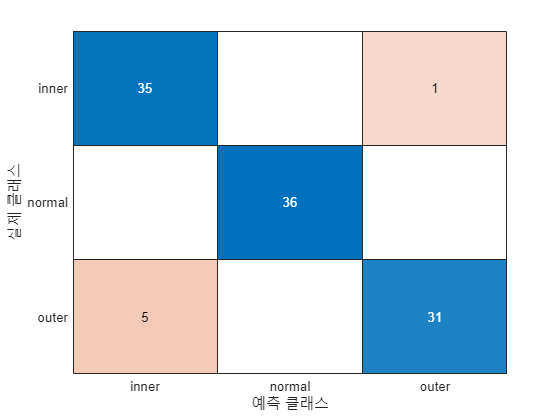

pred = predict(mdl_svm,X_test);
figure;
ldeResubCM = confusionchart(Y_test, pred);

**Classifier 2: KNN**

rng(10); % For reproducibility

mdl_knn = fitcknn(X_train,Y_train)

mdl_knn =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'inner'  'normal'  'outer'}
           ScoreTransform: 'none'
          NumObservations: 432
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


mlResubErr_knn = resubLoss(mdl_knn)

mlResubErr_knn = 0

cp = cvpartition(Y_train,'KFold',10)  %k-fold

cp = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43
          IsCustom: 0

cvml = crossval(mdl_knn,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0579

pred = predict(mdl_knn,X_test)

pred = 108×1 cell 배열
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


loss_knn = loss(mdl_knn,X_test,Y_test)

loss_knn = 0.0185

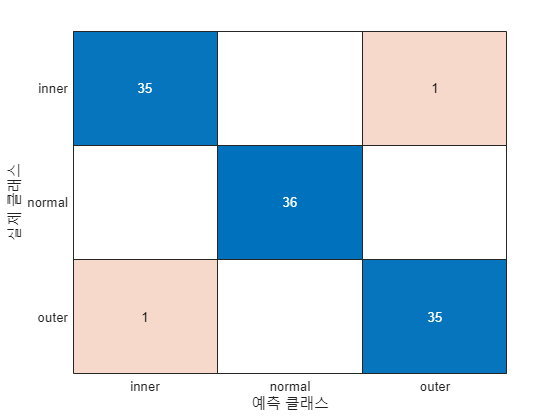

figure
KNNResubCM = confusionchart(Y_test,pred);

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.14815 |    0.034784 |     0.14815 |     0.14815 |           19 |     spearman |         true |
|    2 | Accept |     0.66667 |    0.021145 |     0.14815 |     0.16876 |            1 |      jaccard |         true |
|    3 | Best   |    0.074074 |    0.017909 |    0.074074 |     0.08762 |           10 |       cosine |         true |
|    4 | Accept |     0.10185 |     0.02126 |    0.074074 |    0.083558 |            2 |    cityblock |        false |
|    5 | Accept |     0.26852 |    0.019075 |   

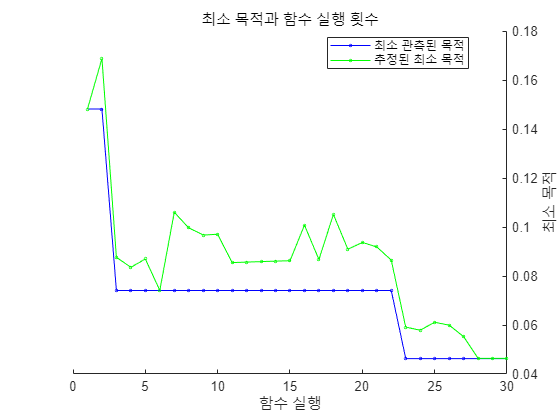

Mdl =   ClassificationKNN
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [inner    normal    outer]
                       ScoreTransform: 'none'
                      NumObservations: 108
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'cityblock'
                         NumNeighbors: 3


  Properties, Methods


Mdl = fitcknn(cwru_test,class_test,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

## **Section 2: Classification on Selected features**

Wrapper Type Feature Selection: Sequential Feature Selection

### `2.1. Automatically Select Feature Number - SVM`

lossfun = 'mincost';
dir = 'forward';
opts = statset('Display','iter');

%%% For SVM
fun = @(XT,yT,Xt,yt)loss(fitcecoc(XT,yT),Xt,yt, 'Lossfun', lossfun);    % svm 이용

[inmodel_svm, history_svm] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 9번 열 추가, 기준값 0.00491221
2단계, 1번 열 추가, 기준값 0.00246903
3단계, 5번 열 추가, 기준값 0.00203949
4단계, 6번 열 추가, 기준값 0.00183043
5단계, 3번 열 추가, 기준값 0.0016686
최종적으로 포함된 열: 1 3 5 6 9 


inmodel_svm = 1×11 logical 배열
   1   0   1   0   1   1   0   0   1   0   0


history_svm = 다음 필드를 포함한 struct :
      In: [5×11 logical]
    Crit: [0.0049 0.0025 0.0020 0.0018 0.0017]


% K-fold Loss of all  features
cvmdl = crossval(mdl_svm); % Performs stratified 10-fold cross-validation
accuracy = 1 - kfoldLoss(cvmdl)

accuracy = 0.9190

% K-fold Loss of selected features
idx_select_Asvm = find(inmodel_svm);     
cwru_train_select  = cwru_train(:, idx_select_Asvm);
cwru_test_select  = cwru_test(:, idx_select_Asvm);

mdl_select_Asvm = fitcecoc(cwru_train_select, class_train);
cvmdl_select = crossval(mdl_select_Asvm); 
accuracy_select = 1 - kfoldLoss(cvmdl_select)

accuracy_select = 0.9213

% Test Loss of all  features
error = loss(mdl_svm, cwru_test, class_test);
SVM_accuracy = 1-error

SVM_accuracy = 0.9444

% Test Loss of selected  features
error_select = loss(mdl_select_Asvm, cwru_test_select,class_test);
ASVM_accuracy_select = 1-error_select

ASVM_accuracy_select = 0.9444

### 2.2  `Automatically Select Feature Number` - KNN

%% For KNN
k =10;
fun = @(XT,yT,Xt,yt)loss(fitcknn(XT,yT, 'NumNeighbors', k, 'Standardize', ...
    1),Xt,yt, 'Lossfun', lossfun);                                      % knn 이용

opts = statset('Display','iter');
[inmodel_knn, history_knn] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 11번 열 추가, 기준값 0.0023555
2단계, 4번 열 추가, 기준값 0.00193277
3단계, 1번 열 추가, 기준값 0.00151072
4단계, 5번 열 추가, 기준값 0.00118748
5단계, 6번 열 추가, 기준값 0.00107302
최종적으로 포함된 열: 1 4 5 6 11 


inmodel_knn = 1×11 logical 배열
   1   0   0   1   1   1   0   0   0   0   1


history_knn = 다음 필드를 포함한 struct :
      In: [5×11 logical]
    Crit: [0.0024 0.0019 0.0015 0.0012 0.0011]


% K-fold Loss of all  features
cvmdl = crossval(mdl_knn); % Performs stratified 10-fold cross-validation
accuracy = 1 - kfoldLoss(cvmdl)

accuracy = 0.9352

% K-fold Loss of selected features
idx_select_Aknn = find(inmodel_knn);     
cwru_train_select  = cwru_train(:, idx_select_Aknn);
cwru_test_select  = cwru_test(:, idx_select_Aknn);

mdl_select_Aknn = fitcknn(cwru_train_select, class_train);
cvmdl_select = crossval(mdl_select_Aknn); 
accuracy_select = 1 - kfoldLoss(cvmdl_select)

accuracy_select = 0.9537

% Test Loss of all  features
error = loss(mdl_knn, cwru_test, class_test);
KNN_accuracy = 1-error

KNN_accuracy = 0.9815

% Test Loss of selected  features
error_select = loss(mdl_select_Aknn, cwru_test_select,class_test);
AKNN_accuracy_select = 1-error_select

AKNN_accuracy_select = 0.9259

### 2.3. Manually Select Feature Number - SVM

rng(0)
% 전체 feature가 선택/제외될때까지 selection 진행
nfeat = length(cwru_train(1, :));
[inmodel, history] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir, 'nfeatures', nfeat)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 11번 열 추가, 기준값 0.0023555
2단계, 4번 열 추가, 기준값 0.00193277
3단계, 1번 열 추가, 기준값 0.00151072
4단계, 5번 열 추가, 기준값 0.00118748
5단계, 6번 열 추가, 기준값 0.00107302
6단계, 8번 열 추가, 기준값 0.00107302
7단계, 3번 열 추가, 기준값 0.00107302
8단계, 2번 열 추가, 기준값 0.001022
9단계, 7번 열 추가, 기준값 0.00113251
10단계, 9번 열 추가, 기준값 0.00118762
11단계, 10번 열 추가, 기준값 0.00139246
최종적으로 포함된 열: all


inmodel = 1×11 logical 배열
   1   1   1   1   1   1   1   1   1   1   1


history = 다음 필드를 포함한 struct :
      In: [11×11 logical]
    Crit: [0.0024 0.0019 0.0015 0.0012 0.0011 0.0011 0.0011 0.0010 0.0011 0.0012 0.0014]


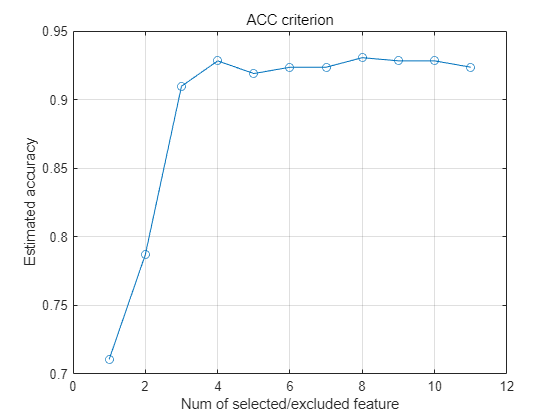

% Accuracy during feataure selection/exclusion
feat_num = length(history.In(:,1));
accuracy_hst = zeros(feat_num, 1);

for i=1:feat_num
    idx_hst = find(history.In(i, :));   % hitory: feature를 선택/제외한 전체 기록
    mdl_hst = fitcecoc(cwru_train(:,idx_hst), class_train);
    cvmdl_hst = crossval(mdl_hst); % Performs stratified 10-fold cross-validation
    accuracy_hst(i) = 1 - kfoldLoss(cvmdl_hst);
end
figure
plot(accuracy_hst, '-o'); title("ACC criterion");   grid on;
xlabel("Num of selected/excluded feature"); ylabel("Estimated accuracy");

% Selected features of Test data
fselect=8;
idx_select_Msvm = find(history.In(fselect, :));      % hitory: feature를 선택/제외한 전체 기록
cwru_train_select  = cwru_train(:, idx_select_Msvm);
cwru_test_select  = cwru_test(:, idx_select_Msvm);

% Test Loss of All  features
error = loss(mdl_svm, cwru_test, class_test);
SVM_accuracy = 1-error

SVM_accuracy = 0.9444

% Test Loss of Selected features
mdl_select_Msvm = fitcecoc(cwru_train_select, class_train);
error_select = loss(mdl_select_Msvm, cwru_test_select,class_test);
MSVM_accuracy_select = 1-error_select

MSVM_accuracy_select = 0.9259

### 2.4. Manually Select Feature Number - KNN

rng(0)
% 전체 feature가 선택/제외될때까지 selection 진행

[inmodel, history] = sequentialfs(fun, cwru_train, class_train, 'cv', cv,...
    'options',opts, 'direction', dir, 'nfeatures', nfeat)

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 11번 열 추가, 기준값 0.0023555
2단계, 4번 열 추가, 기준값 0.00193277
3단계, 1번 열 추가, 기준값 0.00151072
4단계, 5번 열 추가, 기준값 0.00118748
5단계, 6번 열 추가, 기준값 0.00107302
6단계, 8번 열 추가, 기준값 0.00107302
7단계, 3번 열 추가, 기준값 0.00107302
8단계, 2번 열 추가, 기준값 0.001022
9단계, 7번 열 추가, 기준값 0.00113251
10단계, 9번 열 추가, 기준값 0.00118762
11단계, 10번 열 추가, 기준값 0.00139246
최종적으로 포함된 열: all


inmodel = 1×11 logical 배열
   1   1   1   1   1   1   1   1   1   1   1


history = 다음 필드를 포함한 struct :
      In: [11×11 logical]
    Crit: [0.0024 0.0019 0.0015 0.0012 0.0011 0.0011 0.0011 0.0010 0.0011 0.0012 0.0014]


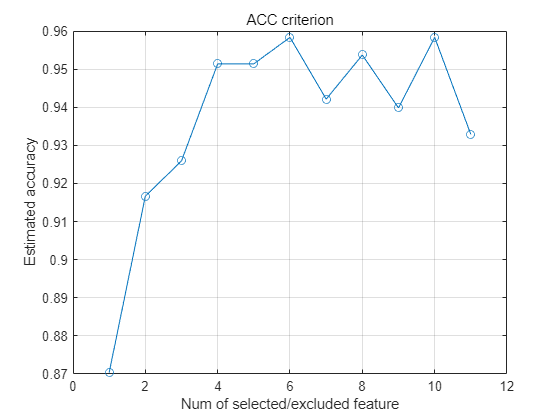

% Accuracy during feataure selection/exclusion
feat_num = length(history.In(:,1));
accuracy_hst = zeros(feat_num, 1);

for i=1:feat_num
    idx_hst = find(history.In(i, :));   % hitory: feature를 선택/제외한 전체 기록
    mdl_hst = fitcknn(cwru_train(:,idx_hst), class_train);
    cvmdl_hst = crossval(mdl_hst); % Performs stratified 10-fold cross-validation
    accuracy_hst(i) = 1 - kfoldLoss(cvmdl_hst);
end
figure
plot(accuracy_hst, '-o'); title("ACC criterion");   grid on;
xlabel("Num of selected/excluded feature"); ylabel("Estimated accuracy");

% Selected features of Test data
fselect=10;
idx_select_Mknn = find(history.In(fselect, :));      % hitory: feature를 선택/제외한 전체 기록
cwru_train_select  = cwru_train(:, idx_select_Mknn);
cwru_test_select  = cwru_test(:, idx_select_Mknn);

% Test Loss of All  features
error = loss(mdl_knn, cwru_test, class_test);
KNN_accuracy = 1-error

KNN_accuracy = 0.9815

% Test Loss of Selected features
mdl_select_Mknn = fitcknn(cwru_train_select, class_train);
error_select = loss(mdl_select_Mknn, cwru_test_select,class_test);
MKNN_accuracy_select = 1-error_select

MKNN_accuracy_select = 0.9444

### 2.5. Confusion Matrix

% figure;
% class_svm = predict(mdl_svm, cwru_test);
% class_knn = predict(mdl_knn, cwru_test);
% class_Asvm = predict(mdl_select_Asvm, cwru_test);
% class_Aknn = predict(mdl_select_Aknn, cwru_test);
% class_Msvm = predict(mdl_select_Msvm, cwru_test);
% class_Mknn = predict(mdl_select_Msvm, cwru_test);
% C_svm = confusionmat(class_cwru_test, class_svm);
% C_knn = confusionmat(class_cwru_test, class_knn);
% C_Asvm = confusionmat(class_cwru_test, class_Asvm);
% C_Aknn = confusionmat(class_cwru_test, class_Aknn);
% C_Msvm = confusionmat(class_cwru_test, class_Msvm);
% C_Mknn = confusionmat(class_cwru_test, class_Mknn);
% 
% subplot(3, 2, 1);   confusionchart(C_svm);          title("Confusion matrix of PCA reduced data");
% subplot(3, 2, 2);   confusionchart(C_knn);       title("Confusion matrix of selected data");
% % subplot(3, 2, 3);   confusionchart(C_Asvm);       title("Confusion matrix of selected data");
% % subplot(3, 2, 4);   confusionchart(C_Aknn);       title("Confusion matrix of selected data");
% % subplot(3, 2, 5);   confusionchart(C_Msvm);       title("Confusion matrix of selected data");
% % subplot(3, 2, 6);   confusionchart(C_Mknn);       title("Confusion matrix of selected data");


## **Section 3: Classification on Reduced Features**

**Use: **[`coeff = pca(X)`](https://kr.mathworks.com/help/stats/pca.html?lang=en#d123e644629)`, `[`coeff = pca(X,Name,Value)`](https://kr.mathworks.com/help/stats/pca.html?lang=en#d123e644661)

### `3.1. SVM Feature Reduce`

**Apply PCA**

rng(0)

[coeff, scores_train, ~, ~, explained, pcaCenter] = pca(cwru_train);

**Select  PCA coefficient with 95% importance**

explain_standard = .95;     
num = find(cumsum(explained)/sum(explained) >= explain_standard, 1)

num = 5

**Feature Reduction Analysis**

coeff = coeff(:,1:num);
scores_train = scores_train(:,1:num);

[n,p] = size(cwru_train);
meanX = mean(cwru_train,1);

Xfit = repmat(meanX,n,1) + scores_train(:,1:num)*coeff(:,1:num)';

**Plot fitted plane and residual**

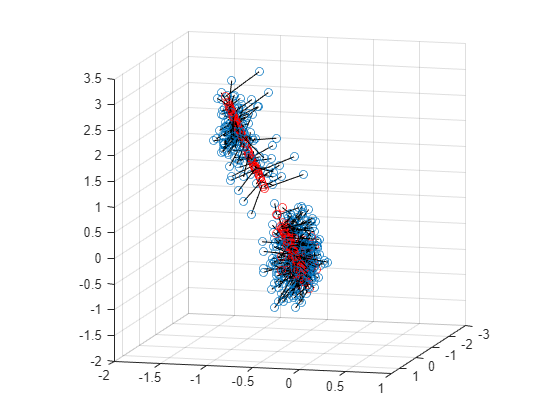

figure
hold on
plot3(cwru_train(:, 1),cwru_train(:, 2),cwru_train(:, 3), 'o');
X1 = [cwru_train(:, 1), Xfit(:, 1), nan*ones(length(cwru_train), 1)];
X2 = [cwru_train(:, 2), Xfit(:, 2), nan*ones(length(cwru_train), 1)];
X3 = [cwru_train(:, 3), Xfit(:, 3), nan*ones(length(cwru_train), 1)];
plot3(X1', X2', X3', '-k', Xfit(:, 1),Xfit(:, 2),Xfit(:, 3), 'or')
grid on

axis([-3 1.5 -2 1 -2 3.5]);
axis square
view(105,10);

**Train SVM model: PCA data**

mdl_pca_svm = fitcecoc(scores_train, class_train);

**K-fold Loss : PCA vs Feature Selection**

cvmdl_pca = crossval(mdl_pca_svm);
accuracy_pca = 1 - kfoldLoss(crossval(mdl_pca_svm))

accuracy_pca = 0.8912

accuracy_select = 1 - kfoldLoss(crossval(mdl_select_Asvm))

accuracy_select = 0.9259

**Covert Test data to PCA reduced dimension**

Convert Test data from originial coordinate to PCA vectors

[ntest,ptest] = size(cwru_test);
mu = repmat(pcaCenter, ntest, 1);
cwru_test_pca = (cwru_test - mu)/coeff';

**Confusion Matrix : PCA vs Feature Selection**

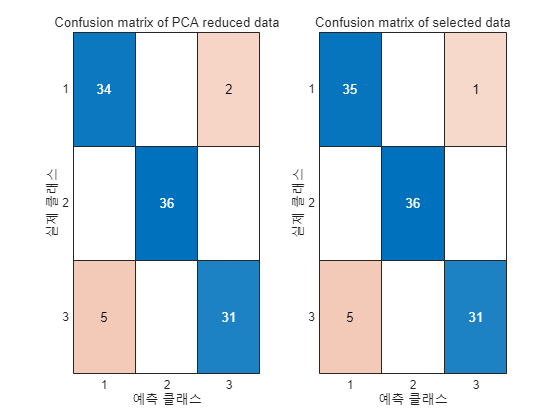

% Calculate Confusion matrix
idx = idx_select_Asvm;

class_pca    = predict(mdl_pca_svm, cwru_test_pca);
class_select = predict(mdl_select_Asvm, cwru_test(:, idx));

C_pca = confusionmat(class_test, class_pca);
C_select = confusionmat(class_test, class_select);

% Plot Confusion Matrix
figure
subplot(1, 2, 1);   confusionchart(C_pca);          title("Confusion matrix of PCA reduced data");
subplot(1, 2, 2);   confusionchart(C_select);       title("Confusion matrix of selected data");

### `3.1. KNN Feature Reduce`

**Apply PCA**

rng(0)

[coeff, scores_train, ~, ~, explained, pcaCenter] = pca(cwru_train);

**Select  PCA coefficient with 95% importance**

explain_standard = .95;     
num = find(cumsum(explained)/sum(explained) >= explain_standard, 1)

num = 5

**Feature Reduction Analysis**

coeff = coeff(:,1:num);
scores_train = scores_train(:,1:num);

[n,p] = size(cwru_train);
meanX = mean(cwru_train,1);

Xfit = repmat(meanX,n,1) + scores_train(:,1:num)*coeff(:,1:num)';

**Plot fitted plane and residual**

figure
hold on
plot3(cwru_train(:, 1),cwru_train(:, 2),cwru_train(:, 3), 'o');
X1 = [cwru_train(:, 1), Xfit(:, 1), nan*ones(length(cwru_train), 1)];
X2 = [cwru_train(:, 2), Xfit(:, 2), nan*ones(length(cwru_train), 1)];
X3 = [cwru_train(:, 3), Xfit(:, 3), nan*ones(length(cwru_train), 1)];
plot3(X1', X2', X3', '-k', Xfit(:, 1),Xfit(:, 2),Xfit(:, 3), 'or')
grid on

axis([-3 1.5 -2 1 -2 3.5]);
axis square
view(105,10);

**Train SVM model: PCA data**

mdl_pca_knn = fitcknn(scores_train, class_train);

**K-fold Loss : PCA vs Feature Selection**

cvmdl_pca = crossval(mdl_pca_knn);
accuracy_pca = 1 - kfoldLoss(crossval(mdl_pca_knn))

accuracy_pca = 0.9329

accuracy_select = 1 - kfoldLoss(crossval(mdl_select_Aknn))

accuracy_select = 0.9583

**Covert Test data to PCA reduced dimension**

Convert Test data from originial coordinate to PCA vectors

[ntest,ptest] = size(cwru_test);
mu = repmat(pcaCenter, ntest, 1);
cwru_test_pca = (cwru_test - mu)/coeff';

**Confusion Matrix : PCA vs Feature Selection**

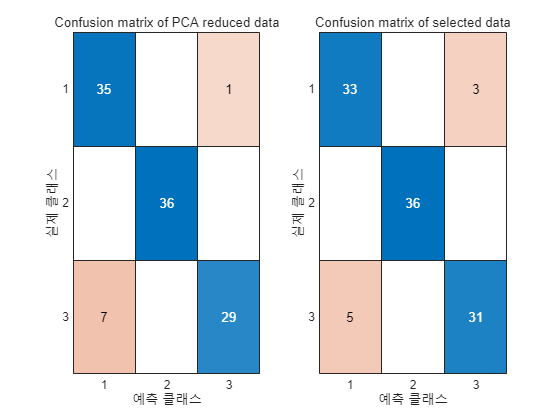

% Calculate Confusion matrix
idx = idx_select_Aknn;

class_pca    = predict(mdl_pca_knn, cwru_test_pca);
class_select = predict(mdl_select_Aknn, cwru_test(:, idx));

C_pca = confusionmat(class_test, class_pca);
C_select = confusionmat(class_test, class_select);

% Plot Confusion Matrix
figure
subplot(1, 2, 1);   confusionchart(C_pca);          title("Confusion matrix of PCA reduced data");
subplot(1, 2, 2);   confusionchart(C_select);       title("Confusion matrix of selected data");

## Discussion 

- **Classification was performed using both the SVM and KNN models on the CWRU Feature Dataset**, focusing on three classes: Inner, Outer, and Normal. Although the assignment instructions specify that all features should be used for classification, it was determined that using all features resulted in 100% accuracy, making it difficult to compare the performance of the classification models. Therefore, only the following features were considered: [4, 9, 14, 17, 20, 22, 26, 27, 32, 35, 41]. The classification results for the three classes based on these selected features are shown below.

- As a result of performing classification using the SVM model,

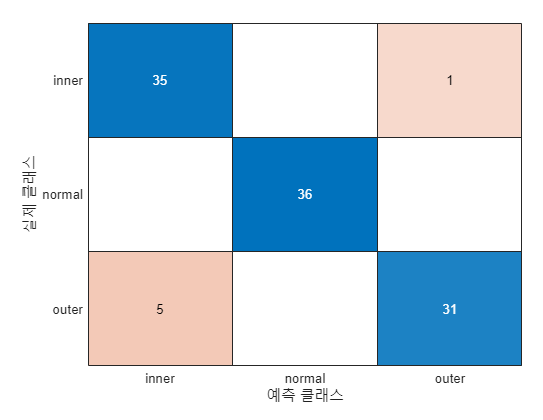

- As a result of performing classification using the KNN model,

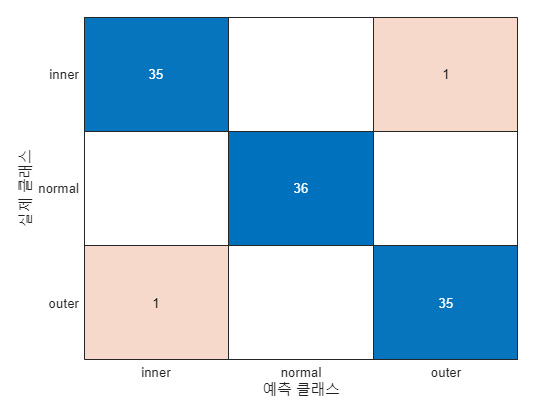

It was confirmed that the classification performance of the KNN model was higher than that of the SVM model. The possible reasons for this result are the small amount of data and the simplicity of the data distribution. Considering all features for classification, it can be inferred that the accuracy reached 100%, indicating that the distribution of the features is not significantly overlapping.

**        2. Feature selection was conducted for the CWRU data classification using both KNN and SVM models.**

- After performing automatic feature selection in the SVM model,

                    

- After performing automatic feature selection in the KNN model,

                    

- After performing manual feature selection in the SVM model,

                  

- After performing manual feature selection in the KNN model,

                

As a result of performing four different feature selection methods and comparing the classification performance, it was found that **Manually_KNN** and **Automatically_SVM** showed the best performance. However, the KNN model without feature selection had the highest accuracy at 0.98, which I believe, as discussed in **Discussion 1**, is due to the simplicity of the data.

**    3. Feature reduction was performed using PCA (Principal Component Analysis).**

- After performing feature reduction in the SVM model,

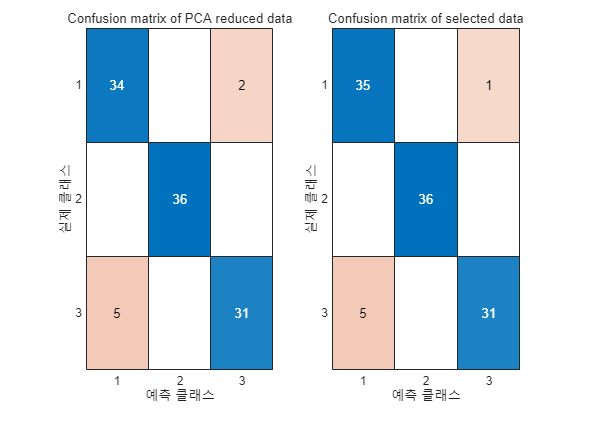

- After performing feature reduction in the KNN model,

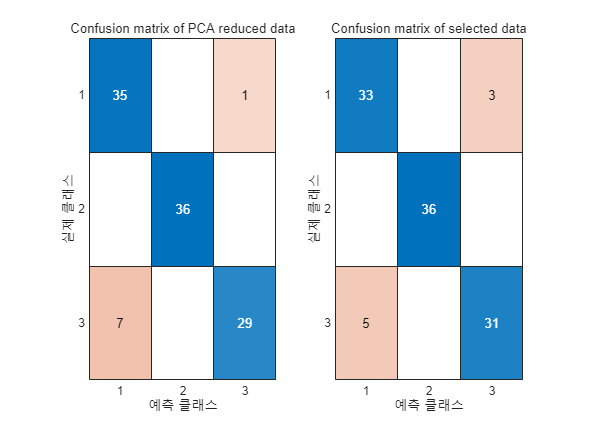

In the SVM model, after performing feature reduction, it was observed that the classification performance improved. However, in the KNN model, the feature reduction did not show any significant difference in performance. I believe this is also due to the simplicity of the feature data.